MECHENG 736/730 - Assignment 1: Measuring and decoding the electroencephalogram (EEG)

Student: Gabriel Werpel Fernandes - gfer533@aucklanduni.ac.nz - UoA ID: 989055637

**Task 5:**

% Load, Extract alphaPower, betaPower, and labels from combinedData
load('combinedEEGData.mat');
alphaPower = combinedData(:, 1);
betaPower = combinedData(:, 2);
labels = combinedData(:, 3);

% Split the data into training and testing
alphaTrain = alphaPower(1:34);
betaTrain = betaPower(1:34);
alphaTest = alphaPower(35:36);
betaTest = betaPower(35:36);

% Create training and testing matrices
trainingData = [alphaTrain, betaTrain];
testingData = [alphaTest, betaTest];
group = labels(1:34); % labels for the training data

% Train the SVM classifier
SVMModel = fitcsvm(trainingData, group);

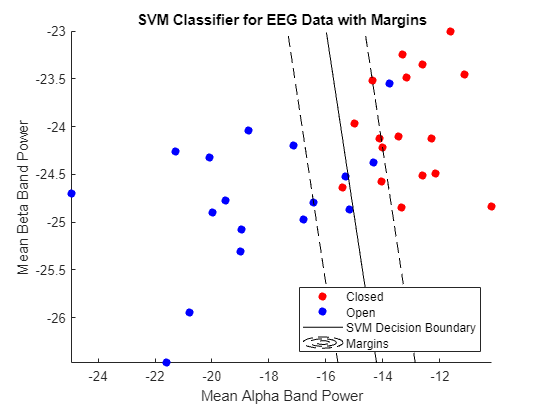

% Plotting
figure;

% Plot training data
scatter(alphaTrain(group == 0), betaTrain(group == 0), 'ro', 'filled'); % Eyes closed
hold on;
scatter(alphaTrain(group == 1), betaTrain(group == 1), 'bo', 'filled'); % Eyes open

% Plot SVM decision boundary and margins
d = 0.02; % Step size of the grid
[x1Grid, x2Grid] = meshgrid(min(alphaPower):d:max(alphaPower), min(betaPower):d:max(betaPower));
xGrid = [x1Grid(:), x2Grid(:)];
[~, scores] = predict(SVMModel, xGrid);

% Plot decision boundary
contour(x1Grid, x2Grid, reshape(scores(:,2), size(x1Grid)), [0 0], 'k');

% Plot margins
contour(x1Grid, x2Grid, reshape(scores(:,2), size(x1Grid)), [-1 1], 'k--');

xlabel('Mean Alpha Band Power');
ylabel('Mean Beta Band Power');
legend('Closed', 'Open', 'SVM Decision Boundary', 'Margins','Location', 'southeast');
title('SVM Classifier for EEG Data with Margins');

Comparing the Results from Classifier with SVM:

% Number of trials
numTrials = length(labels);

% Initialize accuracy storage
accuracies = zeros(numTrials/2, 1);
trialPairs = zeros(numTrials/2, 2);

% Loop through the data for cross-validation
for i = 1:2:numTrials-1
    % Define the test indices
    testIndices = [i, i+1];
    
    % Store the trial pair
    trialPairs((i+1)/2, :) = testIndices;
    
    % Define the training indices
    trainIndices = setdiff(1:numTrials, testIndices);
    
    % Split the data into training and testing
    alphaTrain = alphaPower(trainIndices);
    betaTrain = betaPower(trainIndices);
    alphaTest = alphaPower(testIndices);
    betaTest = betaPower(testIndices);
    
    % Create training and testing matrices
    trainingData = [alphaTrain, betaTrain];
    testingData = [alphaTest, betaTest];
    group = labels(trainIndices); % labels for the training data
    
    % Train the SVM classifier
    SVMModel = fitcsvm(trainingData, group);
    
    % Predict using the trained SVM model
    [predictedLabels, ~] = predict(SVMModel, testingData);
    
    % Compute accuracy for this iteration
    accuracies((i+1)/2) = sum(predictedLabels == labels(testIndices)) / length(testIndices);
end

% Display the results
fprintf('Trial Pair\tAccuracy\n');

Trial Pair	Accuracy


fprintf('-------------------------\n');

-------------------------


for i = 1:size(trialPairs, 1)
    fprintf('%d & %d\t\t%.2f%%\n', trialPairs(i, 1), trialPairs(i, 2), accuracies(i) * 100);
end

1 & 2		100.00%
3 & 4		100.00%
5 & 6		100.00%
7 & 8		100.00%
9 & 10		50.00%
11 & 12		100.00%
13 & 14		100.00%
15 & 16		100.00%
17 & 18		100.00%
19 & 20		50.00%
21 & 22		100.00%
23 & 24		50.00%
25 & 26		100.00%
27 & 28		100.00%
29 & 30		50.00%
31 & 32		100.00%
33 & 34		50.00%
35 & 36		100.00%


% Compute overall accuracy
overallAccuracy = mean(accuracies);
fprintf('Overall SVM Accuracy: %.2f%%\n', overallAccuracy * 100);

Overall SVM Accuracy: 86.11%


Answer: We find a difference in the performance of the two classifiers. The classifier from Task.3 has an accuracy of 88.89%, which is slightly higher than the 86.11% accuracy achieved by the SVM classifier.